clear all; close all; clc;
%%%%%%%%%ALLOCATIONS%%%%%%%%%%
counter_line = 1

counter_line = 1

counter_fsm_x = 2

counter_fsm_x = 2

counter_fsm_y = 2

counter_fsm_y = 2

SW = zeros(1,18)

SW =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Frame_Buffer = zeros(480,640); %(row,col) (y,x)
rand_num = randi([0 1])

rand_num = 1

FSM_MEMORY = zeros(2,642);
threedots = [0 0 0]

threedots =      0     0     0


%%%%%%%%%%STATES%%%%%%%%%%%%%%%
middle_dot_0 = 1

middle_dot_0 = 1

middle_dot_1 = 2

middle_dot_1 = 2

random_line = 3

random_line = 3

calculate_1 = 4

calculate_1 = 4

stop_FSM = 5

stop_FSM = 5

%%%%%%%%%%%INITIALS%%%%%%%%%%%%
%|SW6||SW5||SW4||SW3||SW2||SW1|
%   0   0   0     1     0   1
%   ->5


SW(1,18) = 0

SW =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


debug_stop = 1

debug_stop = 1

reset = 1

reset = 1

flag = 1

flag = 1

FSM_MEMORY_SWITCH = 0

FSM_MEMORY_SWITCH = 0

SW(1,1:8) = rule_SW(94)

SW =      0     1     1     1     1     0     1     0     0     0     0     0     0     0     0     0     0     0


state = 1

reset = 0

state = 4

state = 5

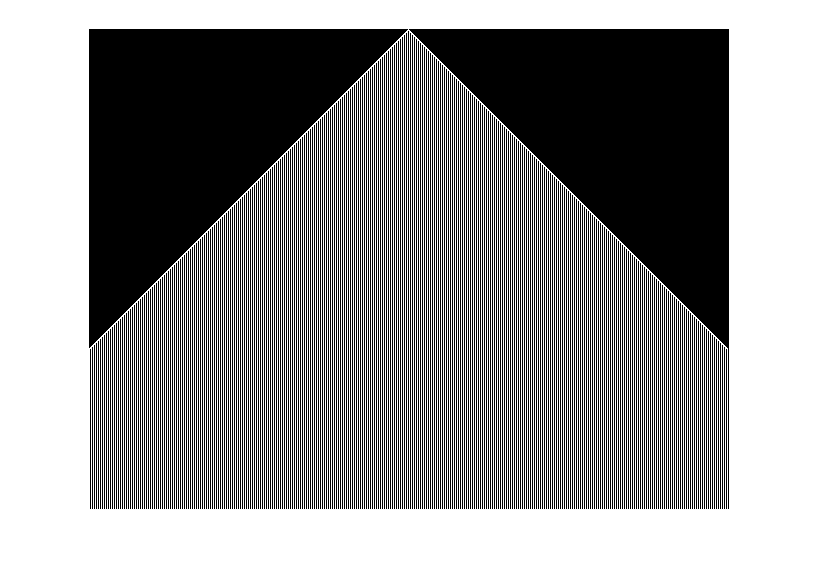



while(debug_stop)
    rand_num = randi([0 1]);
    if(reset)
        if(~SW(1,18))
            state = middle_dot_0
        else
            state = random_line
        end
        reset = 0%%
    else
        switch state
            case middle_dot_0
                Frame_Buffer(1,320) = 1;
                FSM_MEMORY(1, 321) = 1;
                state = calculate_1
            case random_line
                if(counter_line ~= 640)
                    counter_line = counter_line + 1;
                    Frame_Buffer(1, counter_line) = rand_num;
                    FSM_MEMORY(1, counter_line + 1) = rand_num;
                else
                    state = calculate_1
                end
            case calculate_1
                if(counter_fsm_x ~= 642)
                    
                    A = [FSM_MEMORY(FSM_MEMORY_SWITCH+1,counter_fsm_x-1), FSM_MEMORY(FSM_MEMORY_SWITCH+1,counter_fsm_x), FSM_MEMORY(FSM_MEMORY_SWITCH+1,counter_fsm_x + 1)];
                    threedots = toDecimal(A);
                    switch threedots
                        case 0%000
                            Frame_Buffer(counter_fsm_y,counter_fsm_x-1) = SW(1,1);
                            FSM_MEMORY((~FSM_MEMORY_SWITCH)+1,counter_fsm_x)= SW(1,1);
                        case 1%001
                            Frame_Buffer(counter_fsm_y,counter_fsm_x-1) = SW(1,2);
                            FSM_MEMORY((~FSM_MEMORY_SWITCH)+1,counter_fsm_x)= SW(1,2);
                        case 2%010
                            Frame_Buffer(counter_fsm_y,counter_fsm_x-1) = SW(1,3);
                            FSM_MEMORY((~FSM_MEMORY_SWITCH)+1,counter_fsm_x)= SW(1,3);
                        case 3%011
                            Frame_Buffer(counter_fsm_y,counter_fsm_x-1) = SW(1,4);
                            FSM_MEMORY((~FSM_MEMORY_SWITCH)+1,counter_fsm_x)= SW(1,4);
                        case 4%100
                            Frame_Buffer(counter_fsm_y,counter_fsm_x-1) = SW(1,5);
                            FSM_MEMORY((~FSM_MEMORY_SWITCH)+1,counter_fsm_x)= SW(1,5);
                        case 5%101
                            Frame_Buffer(counter_fsm_y,counter_fsm_x-1) = SW(1,6);
                            FSM_MEMORY((~FSM_MEMORY_SWITCH)+1,counter_fsm_x)= SW(1,6);
                        case 6%110
                            Frame_Buffer(counter_fsm_y,counter_fsm_x-1) = SW(1,7);
                            FSM_MEMORY((~FSM_MEMORY_SWITCH)+1,counter_fsm_x)= SW(1,7);
                        case 7%111
                            Frame_Buffer(counter_fsm_y,counter_fsm_x-1) = SW(1,8);
                            FSM_MEMORY((~FSM_MEMORY_SWITCH)+1,counter_fsm_x)= SW(1,8);
                        otherwise
                            disp('other value')
                    end
                    counter_fsm_x = counter_fsm_x + 1;
                    FSM_MEMORY(1,1) = FSM_MEMORY(1,641);
                    FSM_MEMORY(1,642) = FSM_MEMORY(1,2);
                    FSM_MEMORY(2,1) = FSM_MEMORY(2,641);
                    FSM_MEMORY(2,642) = FSM_MEMORY(2,2);
                else
                    if(counter_fsm_y ~= 480)
                        counter_fsm_x = 2;
                        counter_fsm_y = counter_fsm_y + 1;
                        FSM_MEMORY_SWITCH = ~FSM_MEMORY_SWITCH;
                    else
                        state = stop_FSM
                    end
                end
            case stop_FSM
                imshow(Frame_Buffer)
            otherwise
                disp('other value')
        end
    end
end

function y = toDecimal(A)

    % convert x to a string array
    str_A = num2str(A);
    % remove the spaces in the string, so it 
    % becomes '10000000'
    str_A(isspace(str_A)) = '';
    % now use BIN2DEC to convert the binary 
    % string to a decimal number
    y = bin2dec(str_A);
end



function y = rule_SW(s)
   s = dec2bin(s,8);   
   y = s-'0';
   y = flip(y,2);
   %lsb--------msb
   %    10000000 -> 1
end






